clear; clc;
load("C:\Users\BLooDek\Desktop\numerical-methods\series.mat");

c1 = 3*((-1)^series_NumerMeth(ID + 2))*series_NumerMeth(ID);
c2 = ((-1)^series_NumerMeth(ID + 3))*series_NumerMeth(ID + 1);

if abs(c1) < abs(c2)
c2 = ((-1)^series_NumerMeth(ID + 2))*series_NumerMeth(ID);
c1 = 3*((-1)^series_NumerMeth(ID + 3))*series_NumerMeth(ID + 1);
end
if abs(c1) == abs(c2)
c1 = c1*2;
end

f = @(x) c1*cos(x) -(c2*x)

f = function_handle with value:
    @(x)c1*cos(x)-(c2*x)


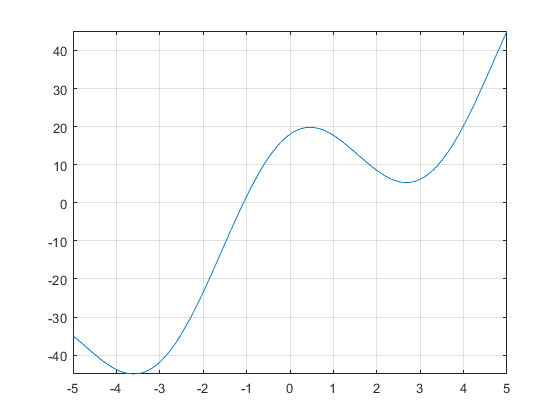

syms x
f1 = diff(f,x);
f1 = matlabFunction(f1);

fplot(f)
grid

[x_star_1, i] = NumerMeth_tasks_01_02(f, f1, 1, 0.001, 100);
x_star_1

x_star_1 =   -1.073454648053623
